## **AERO40003 Computing and Numerical Methods 1**

## **Coursework Project Part 2**

## ** 2021-2022**

## **Dr. Elnaz Naghibi**

## **Due Date: 25 March 2022**

### **Question 1 [5%]**

Plot the function $f\left(x\right)=\cos \;x\;\left(e^{2x} -2e^x +1\right)$ in the interval $\left\lbrack -\pi /4,3\pi /4\right\rbrack$ and find its two roots in the mentioned interval using MATLAB functions.

Using the derivative of the function and appropriate initial guesses from the plot of the function, verify which root can be found by fixed-point method. Use the fixed-point method to approximate this root and use the Secant method to find the other root (for which the fixed-point method does not work). Show the convergence to each root using appropriate plots and provide the codes for both methods.  Consider the tolerance value to be equal to 1e-6.

**Answer:**

You can use this space to explain the answers and include equations as needed using either Latex code or the live script equation editor from the tab "insert".

% Use this box for coding. 
% Outputs and graphs will be displayed on the right panel.
% To avoid submitting multiple files, please include functions at the bottom of your scripts.
format long g
f = @(x) (cos(x)).*(exp(2.*x)-2.*exp(x)+1);
x = linspace(-pi/4,3*pi/4,1000000);
y = f(x);
xint1 = [0 0.5];
xint2 = [1 2];
x1 = fzero(f,xint1);
x2 = fzero(f,xint2);
ans = [x1,x2]

ans =          0    1.5708



%Derivative of f is -(exp(x)-1)((exp(x)-1)sin(x)-2exp(x)cos(x))
fd = @(x) -(exp(x)-1).*((exp(x)-1).*sin(x)-2.*exp(x).*cos(x));
yd = fd(x);
xd1 = fd(x1) 

xd1 =      0


xd2 = fd(x2)

xd2 =          -14.5197378708486


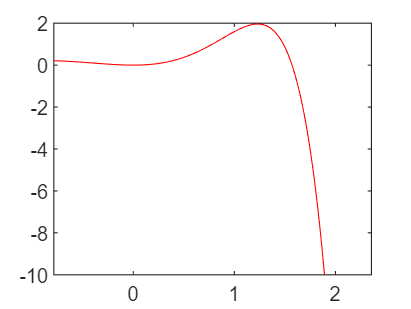

%Since derivative at root x1 is zero, the first root can be found via
%the fixed point method, however the root x2 cannot be found via this
%method
plot(x,y,'r-')
hold on
axis([-pi/4 3*pi/4 -10 2]);
hold off


%To rearrange in terms of x, add x to both sides to have an equation in
%terms of x, i.e. x_n+1 = x_n + cos(x_n)*(e^(2x_n) - 2e^(x_n) + 1)
%It can therefore be concluded that only the root close to 0 can be found
%via the fixed point method as confirmed below


%fixed point method
x0 = -0.1

x0 =                       -0.1


n = 1000000;
eps = 1e-6;
f = @(x) x + (cos(x)).*(exp(2.*x)-2.*exp(x)+1);
g = @(x) (cos(x)).*(exp(2.*x)-2.*exp(x)+1);
k = 1;
x = f(x0);
while k <= n
    x=f(x);
    temp = x;
    if abs(x-x0) < eps
        break
    else 
        k = k + 1;
        x0 = temp; 
    end
end
disp(x)

     -0.000999099662955936



%Works for root x1, root converges to 0 [correct value for x0]
%Doesn't work for other root x2, root still converges to 0

%Using the secant method, we can compute our x value without having to
%evaluate a derivative at x_n and instead use a finite difference approach
%i.e. x_n+1 = x_n - f(x_n)*((x_n - x_n-1)/(f(x_n) - f(x_n-1))
%Change range to 1 to 1.5 for root to converge to 0
x0 = 1.2;
x1 = 1.5;
eps = 100;
while eps > 1e-6
    x2 = x1 - g(x1)*((x1-x0))/(g(x1)-g(x0));
    x0 = x1;
    x1 = x2;
    eps = abs(g(x2)-g(x0));
end
Secconv = x2

Secconv =           1.57079632679548


%Secant method used here to compute root x2 which couldn't be found via
%the fixed point method



### **Question 2 [10%]**

**Part a: [5 %]**

Calculate Legendre polynomial of degree 6 using equation 16 in Handout_4 and MATLAB symbolic toolbox. Compare your resulting polynomial with "legendreP" function in MATLAB. Plot this function in the interval $\left\lbrack -1\ldotp 1\right\rbrack$ and calculate its roots $\eta_i$. Calculate weighting coefficients $w_i$ using the definition in equation 21. Using  $\eta_i$ and $w_i$, calculate the integral of  $\int_{-2}^1 \left({\textrm{ax}}^{10} +{\textrm{bx}}^5 +{\textrm{cx}}^2 \right)\;\textrm{dx}$ for arbitrary values of $a,b,c$ and show that it will be the same as its analytical value.

**Answer:**

%Equation 16 is L_N(x) = (1/(2^N * N!)) * diff((x^2-1)^N)
%Legendre Polynomial Code
N = 6;
%Makes 'b' a symbol
syms b
coeff = 1/(2^N * factorial(N));
N_Df = diff(((b^2 - 1)^N),N);
LP_mine = N_Df * coeff; %output printed to the right 

% Compute simplified symbolic expression
simplifiedExpr = expand(LP_mine)

$$simplifiedExpr = \frac{231\,b^{6}}{16}-\frac{315\,b^{4}}{16}+\frac{105\,b^{2}}{16}-\frac{5}{16}$$

%Makes 'a' a symbol for use in the checker for the lagrange polynomial
syms a
LP_check = legendreP(N,a)

$$LP\_check = \frac{231\,a^{6}}{16}-\frac{315\,a^{4}}{16}+\frac{105\,a^{2}}{16}-\frac{5}{16}$$

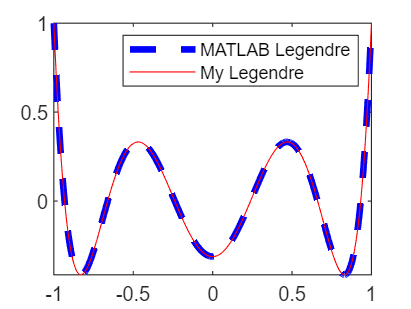

fplot(LP_check,[-1,1],'b--','Linewidth',3)
hold on
%After checking with MATLAB built-in, can see that both match
%Legendre polynomial of degree 6 is (1/16)*(231x^6 - 315x^4 + 105x^2 - 5)
xP = linspace(-1,1,1000000);
LP = @(x) (1/16)*(231*x.^6 - 315*x.^4 + 105*x.^2 - 5);
yP = LP(xP);
%Plotting function and comparing it to actual legendre polynomial from
%matlab
plot(xP,yP,'r-')
legend('MATLAB Legendre','My Legendre')
hold off

p = [231/16 0 -315/16 0 105/16 0 -5/16];
%Solves for the roots of p
eta = roots(p);
eta = eta'

eta =    -0.9325   -0.6612    0.9325    0.6612   -0.2386    0.2386


%Makes 'x' a symbolic variable
syms x
LPDiff = diff(LP,x)

$$LPDiff = \frac{693\,x^{5}}{8}-\frac{315\,x^{3}}{4}+\frac{105\,x}{8}$$

%Finds value of weights 
LPD = @(x) (693*x.^5 - 630*x.^3 + 105*x)*(1/8)

LPD = function_handle with value:
    @(x)(693*x.^5-630*x.^3+105*x)*(1/8)


for val = 1:N
    w(val) = (2/(1-(eta(val))^2)) * (LPD(eta(val)))^(-2);
end
disp(w)

         0.171324492379167         0.360761573048138         0.171324492379171          0.36076157304814         0.467913934572691         0.467913934572691



%Integral is given by the summation of N values of w_N * f(eta_N)
%We want to compute the integral of a general polynomial; 
% a*x^10 + b*x^5 + c*x^2 between the limits of -2 and 1. We therefore
% require a change of variables
a = 1;
b = 1;
Curve = 1;
lb = -2;
ub = 1;
%New function needs to be determined using new variable, t %This bit needs
%to be FIXED
func = @(x) a*x.^10 + b*x.^5 + Curve*x.^2

func = function_handle with value:
    @(x)a*x.^10+b*x.^5+Curve*x.^2


for d = 1:N
    LGI(d) = ((ub-lb)/2)*w(d)*func(((lb+ub)/2)+((ub-lb)*eta(d))/2);
end
LGI = sum(LGI)

LGI =           178.772727272726


integral(@(x) a*x.^10 + b*x.^5 + Curve*x.^2,-2,1)

ans =           178.772727272727


%As can be seen by output on right, the legendre integral and the numerical
%integral are identical.

**Part b: [5 %]**

Use Simpson integration scheme to calculate the below integral for $n=10,20,40,80$. Compare the results with the analytical value and calculate the error in each case. Plot error values versus $n$ and comment on the order of accuaracy of Simpson scheme. Provide the code for the integration and error calculation.


$$\int_0^{\frac{3\pi }{2}} \mathrm{x}\;\textrm{sinx}\;\textrm{dx}$$


**Answer:**

clf
%Using function handle to define function
f = @(x) x.*sin(x);
%Upper and lower limit of integrals
p = 0;
q = 3*pi/2;
x = linspace(p,q,n);
%Difference between the any two x points
h = (x(2)-x(1));
coeffs = [];
%coeffs generates the coefficients for the simpson rule formula
for k = 2:2:n-1
    coeffs(k) = 4;
end
for k = 3:2:n-1
    coeffs(k) = 2;
end
coeffs(1) = 1;
coeffs(n) = 1;
y = f(x);
%Calculates final Simpson Integral
SI = (h/3)*sum((coeffs.*y))

SI =         -0.999992597792997


%Value for [10, 20, 40, 80] = [-0.225182, -0.620758, -0.812639, -0.906895]
ActI = integral(f,0,3*pi/2)

ActI =         -0.999999999999999


P_error = abs((SI-ActI)/ActI) * 100     

P_error =       0.000740220700223837


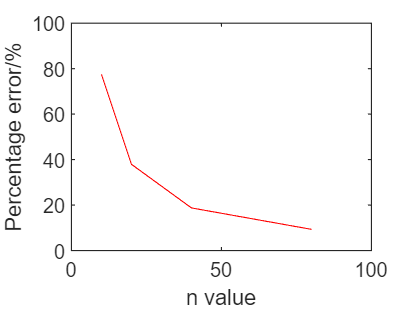

%P_error value for [10 20 40 80] = [77.4818, 37.9242, 18.7361, 9.3105]
n_val = [10 20 40 80];
P_error_val = [77.4818, 37.9242, 18.7361, 9.3105];
plot(n_val,P_error_val,'r-')
hold on
axis([0 100 0 100])
xlabel('n value')
ylabel('Percentage error/%')
hold off

%The order of accuracy of the simpson scheme decays exponentially
%everytime the value of n is increased and is tending to zero percentage
%error.

### **Question 3 [10%]**

**Part a: [5%]**

Use Chebyshev distribution to sample 5 values of function $f\left(x\right)=\frac{1}{\cosh \;x}$ in the interval $\left\lbrack -0\ldotp 5,0\ldotp 5\right\rbrack$. Write a code to calculate the Lagrange interpolating polynomial passing though these points. Increase the number of points to 15 and rebuild the polynomial. Provide graphs to compare the original function and the interpolating polynomial and report the Euclidean norm of error in each case. 

**Answer:**

        -0.475528258147577        -0.293892626146237     -3.06161699786838e-17         0.293892626146237         0.475528258147577



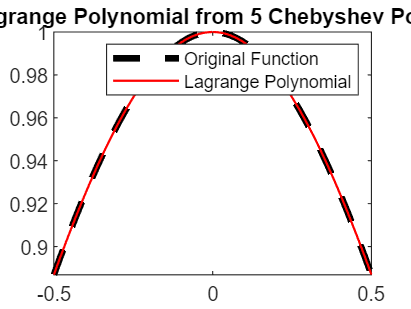

the Euclidean norm of this error is:
      0.000398065414897098



$$ans = \left(3.4026032334081596827930448285189\,x-0.99999999999999981111757733031277\right)\,\left(2.1029244484765347601012962199243\,x+1.0000000000000001167357570872904\right)\,\left(3.4026032334081603254849869383635\,x+1.0000000000000001888824226696873\right)\,\left(2.1029244484765342691283410393627\,x-0.99999999999999988326424291270965\right)-1.0\,\left(3.4026032334081596827930448285189\,x+0.00000000000000010417467896404342787989674116055\right)\,\left(1.2455017279242731018942243741967\,x+0.59227126719962666060504458675965\right)\,\left(5.5055276818846932108734039628907\,x-2.6180339887498942875951459534684\right)\,\left(1.7013016167040798413965224142595\,x+0.5\right)+\left(0.94283766329153981565684610463734\,x+0.4483459517409574075028538870754\right)\,\left(2.1029244484765342691283410393627\,x+0.00000000000000006438349236688751953072408971628\right)\,\left(1.29967878493162542626198679254\,x+0.38196601125010519270038537129931\right)\,\left(5.5055276818846932108734039628907\,x-1.6180339887498942875951459534684\right)-1.0\,\left(3.4026032334081603254849869383635\,x+0.00000000000000010417467896404344755666248472598\right)\,\left(1.7013016167040798413965224142595\,x-0.49999999999999990555878866515639\right)\,\left(1.29967878493162542626198679254\,x-0.61803398874989487944628021109756\right)\,\left(5.276029985580669030704200504409\,x+2.508901348977560103078280068811\right)+\left(1.0514622242382672573074093148217\,x-0.5\right)\,\left(2.1029244484765347601012962199243\,x+0.000000000000000064383492366887534562435540461071\right)\,\left(4.936762096741561044917763879607\,x+1.4508779772705785676139072859122\right)\,\left(1.29967878493162542626198679254\,x-0.38196601125010512055371978890244\right)$$

%Lagrange Polynomial function defined at end of script, here it is simply
%run for 5 and 15 Chebyshev points
LagPolynomial(5)

  Columns 1 through 6

        -0.497260947684137        -0.475528258147577        -0.433012701892219        -0.371572412738697        -0.293892626146237          -0.2033683215379

  Columns 7 through 12

         -0.10395584540888     -3.06161699786838e-17          0.10395584540888           0.2033683215379         0.293892626146237         0.371572412738697

  Columns 13 through 15

         0.433012701892219         0.475528258147577         0.497260947684137



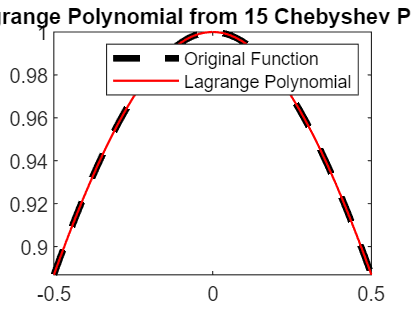

the Euclidean norm of this error is:
      3.32348101527218e-12




LagPolynomial(15)

**Part b: [5%]**

Use 9 equally spaced sample points for the function in part a and find the cubic splines passing through these points. Calculate the Euclidean norm of the error in this case and provide a graph to compare the original function and the cubic splines.

**Answer:**

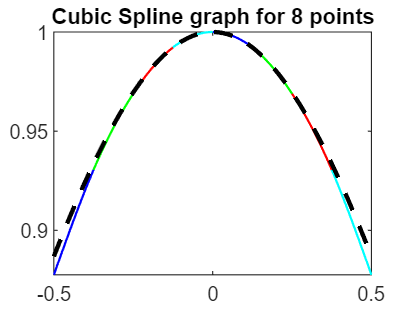

% Cubic Splining


%cleanup
clear
clc
clf
%domain of x and y-values at those points
x = linspace(-0.5,0.5,9);
y = zeros(1, length(x));

for i = 1:length(y)
    y(i) = cos(x(i));
end

%gets values for the curvatures using curvature function defined at end of
%script
Curve = curvature(x,y);

%syms allows 'X' to be used as a variable
syms X;

%creates the splines and keeps them in a set
yi = {};
%figure;
colour = 'bgrcbgrcb';

for i = 1:length(y)-1
   %generates the cubic spline function from equations in handout
   yi{i}= ((Curve(i)/6)*( (x(i+1)-X)^3 / (x(i+1)-x(i)) - (x(i+1)-x(i))*(x(i+1)-X))) + ...
        ((Curve(i+1)/6)*((X-x(i))^3 / (x(i+1)-x(i)) - (x(i+1)-x(i))*(X-x(i)))) + ...
        y(i)*((x(i+1)-X)/(x(i+1)-x(i))) + y(i+1)*((X-x(i))/(x(i+1)-x(i)));
    
   %graphs the spline while generating an overlapping plot
   fplot(yi{i}, [x(i), x(i+1)],colour(i),'LineWidth',1) 
   hold on 
    

end
title('Cubic Spline graph for 8 points')
%Plots actual 1/cosh graph to see how closesly it coincides with the spline
%plots
fplot(@(x) 1./cosh(x),[-0.5 0.5],'k--','LineWidth',2)

disp('Colourful line shows cubic spline and black dashed is the original function')

Colourful line shows cubic spline and black dashed is the original function


%Uses coeffmatrix() function defined at end of script to generate
%coefficient matrix
errormatrix = coeffmatrix(length(x)-2)

errormatrix =     0.6667    0.1667         0         0         0         0         0
    0.1667    0.6667    0.1667         0         0         0         0
         0    0.1667    0.6667    0.1667         0         0         0
         0         0    0.1667    0.6667    0.1667         0         0
         0         0         0    0.1667    0.6667    0.1667         0
         0         0         0         0    0.1667    0.6667    0.1667
         0         0         0         0         0    0.1667    0.6667



%Uses norm() function to find euclidean norm of spline error
CubicSplineError = norm(sqrt(sum(sum(errormatrix.^2))));
disp('The Euclidean norm of this error is: ')

The Euclidean norm of this error is: 


disp(CubicSplineError)

          1.85592145427667



function yds = curvature(x,y)
    %creates empty array to store curvature values (pre-allocation for
    %speed)
    ydd = zeros(1, length(x));

    %creates an array of values to solve for the second derivative
    ys = (y(1:length(y)-2) + y(3:length(y)) - 2.*y(2:length(y)-1)) ./ ((x(2)-x(1))^2);

    %calls the coeff matrix created from below
    solve = coeffmatrix(length(x)-2);

    %solves for curvatures using matlab linsolve function
    ydd(2:length(x)-1) = linsolve(solve, ys');
    yds = ydd;
end


%creates the coefficient matrix to calculate curvatures
function errormatrix = coeffmatrix(x)
    twothirds = 2/3 .* ones(x,1);
    onethirds = 1/6 .* ones(x-1, 1);
%Uses diag() function to assign correct constants to the correct positions
%for a y by y matrix
    vec1 = diag(twothirds);
    vec2 = diag(onethirds, 1);
    vec3 = diag(onethirds, -1);

    errormatrix = vec1+vec2+vec3;

end

function [LagrPoly]= LagPolynomial(Points) 

clf
%Makes 'x' a symbolic variable
syms x

f(x)= 1/cosh(x);
%Predefines points if no input
N = 5;
N=Points-1;

%Generating the Chebyshev points
Chebx = ones(1,N);
for i=1:Points
    Chebx(i)=-cos(pi*((2*(i-1)+1)/(2*N+2)));
end
Chebx=0.5.*Chebx;
disp(Chebx)

%Making the Nodal Lagrangian Polynomials
i=1;
j=1;
for i = 1:Points
    xVal=Chebx(i);
    %VPA function converts to decimal value
    LagPols(i)=vpa(f(Chebx(i)));
    for j= 1:Points
        if i ~= j
            LagPols(i)= LagPols(i) * vpa( (x-Chebx(j)) / (xVal-Chebx(j)) );
        end
    end
    
end
%Sums together each polynomial to generate final one
LagrPoly=vpa(sum(LagPols));
fplot(f(x),[-0.5 0.5],'k--','LineWidth',3)
hold on 
fplot(LagrPoly,[-0.5 0.5],'r-','LineWidth',1)
title(['Lagrange Polynomial from ',num2str(N+1),' Chebyshev Points'])
legend('Original Function','Lagrange Polynomial')

%Generates array for error calculation and size of x_l determines accuracy
%of error calculation
x_l = linspace(-0.5,0.5,200);
error = ones(1,length(x_l));
for k = 1:length(x_l)
    %Simply subtracts values from each x_l to corresponding on Lagrange
    %polynomial
    error(k) = abs(subs(LagrPoly,x,x_l(k)) - f(x_l(k)));
end
%Calculates euclidean norm of error, i.e. magnitude
error = norm(error);
disp("the Euclidean norm of this error is:")
disp(error)

end